# Laboratorio di Automatica (prova del 28 Agosto 2019)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

August 28, 2019

Dept. of Information Engineering, University of Padova

## Esercizio 2

Si consideri un sistema di controllo di posizione di un motore elettrico in corrente continua la cui struttura è analoga a quella di Fig. 1, dove 


$$P(s)\,=\, \frac{Y(s)}{U(s)} \,=\, \frac{k_m}{s(T_m s  + 1)}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,5.2\,,\qquad T_m \,=\,0.03$$


è la funzione di trasferimento del motore, da ingresso in tensione $u$ $[V]$ ad uscita in posizione $y$ $[\mathrm{rad}]$, mentre


$$C(s) \,=\, \frac{U(s)}{E(s)} \,=\; 
K_P \,\left(1 +\, \frac{k_I}{s} \,+\, \frac{k_D\,s}{T_L\,s\,+\,1} \right)\qquad\quad\text{con}\qquad\quad k_I \,=\, 13.0\,,\qquad
k_D \,=\, 0.02\,,\qquad
T_L \,=\, 0.001$$
  

è la funzione di trasferimento di un controllore PID (con derivata ``reale''), con ingresso l'errore di posizione $e\,[\mathrm{rad}]$ ed uscita la tensione di comando $u\,[V]$. 

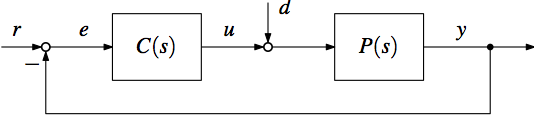

**Figura 1**: Sistema di controllo a retroazione unitaria dall'uscita.

Utilizzando *soltanto* le routines del Control System Toolbox (CST), si svolgano i seguenti punti:

1) Mostrare, mediante il luogo delle radici, come variano i poli del sistema in catena chiusa al variare del guadagno proporzionale $K_P$.

*Soluzione*.

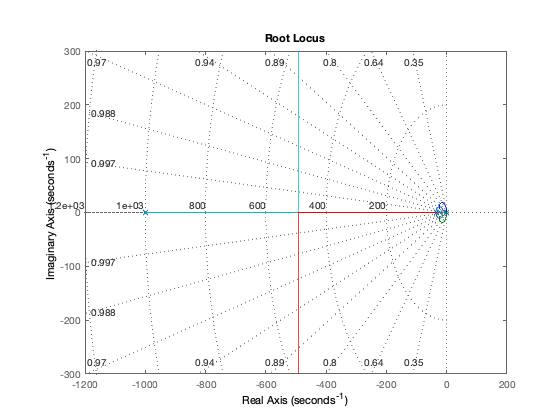

%  define plant tf
k_m = 5.2; 
T_m = 0.03;

s = tf('s');
Ps = k_m/(s*(1+T_m*s));

%  define controller tf
k_i=13;
k_d=0.02;
T_l= 0.001;

% continuous time controller
Cs0 = 1 + k_i/s + k_d*s/(1+T_l*s);

%  loop tf
Ls0 = Ps*Cs0;

%  loop tf - Bode plot
figure;
rlocus(Ls0);
grid on;

2) Ponendo $K_P = 9$, calcolare la funzione di trasferimento in catena chiusa $T(s)$ da riferimento $r$ ad uscita $y$. Mostrare poi la risposta al gradino unitario del sistema in catena chiusa, e determinare quanto valgono sovraelongazione e tempo di assestamento all’1%. 

*Soluzione*.

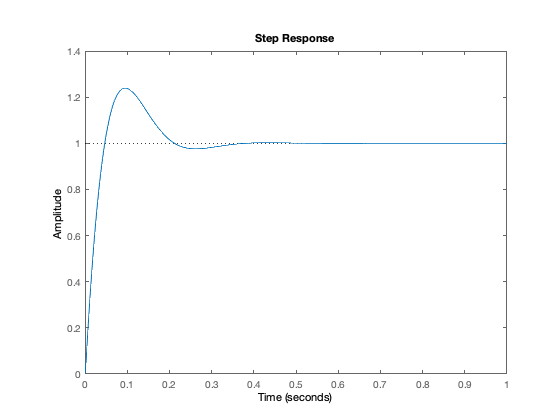

%  set proportional gain
K_p = 9;
Cs = K_p*Cs0;

%  closed-loop tf
T = feedback(Ps*Cs, 1);

%  plot step responses
figure
step(T, 1);


stepinfo(T, 'SettlingTimeThreshold', 0.01)

ans = struct with fields:
        RiseTime: 0.0352
    SettlingTime: 0.3285
     SettlingMin: 0.9094
     SettlingMax: 1.2390
       Overshoot: 23.8958
      Undershoot: 0
            Peak: 1.2390
        PeakTime: 0.0963


La sovraelongazione è pari a $M_p = 23.8958\%$; il tempo di assestamento è pari a $t_{s,1\%} = 0.3285\,\mathrm{s}$.

3) Discretizzare il controllore con un tempo di campionamento $T_s = 5\,\mathrm{ms}$ attraverso il metodo di Tustin con pre-warping alla frequenza ${\bar \omega } = 100\,\mathrm{rad/s}$. 	

Mostrare i diagrammi di Bode del controllore a tempo continuo e della versione discretizzata.

*Soluzione*.

%  samping time
Ts = 5e-3;

%  controller discretization (Tustin with pre-warping)
wbar = 100;

opt = c2dOptions('Method','tustin','PrewarpFrequency',wbar);
Cd_p10 = c2d(Cs, Ts, opt)


Cd_p10 =
 
  59.95 z^2 - 105.9 z + 46.85
  ---------------------------
    z^2 - 0.5628 z - 0.4372
 
Sample time: 0.005 seconds
Discrete-time transfer function.



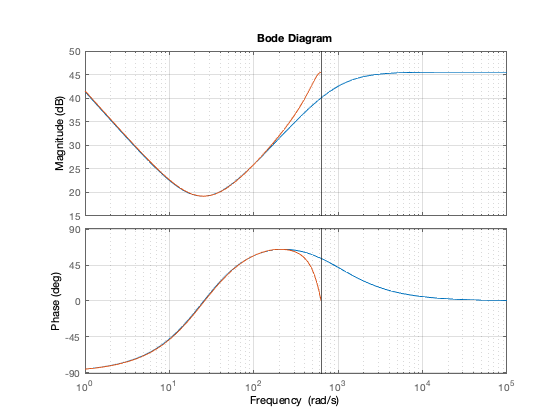

% Bode plot
figure;
bode(Cs);
hold on;
bode(Cd_p10);
grid on;

4) Calcolare il valore di amplificazione e variazione di fase introdotte dalla discretizzazione: 

    • alla frequenza $\bar \omega $

    • alla frequenza ${\tilde \omega } = 500\,\mathrm{rad/s}$ 

*Soluzione*.

%  test frequencies
wtest0 = wbar;
wtest1 = 500;

%  continuous-time controller gain & phase at test frequencies
[magc1, phac1] = bode(Cs, wtest1); % magnitudes (not dB) and phases in degrees
[magc0, phac0] = bode(Cs, wtest0);

%  discrete-time controller gain & phase at test frequencies
[magd1,phad1] = bode(Cd_p10,wtest1); 
[magd0,phad0] = bode(Cd_p10,wtest0);

%  phase distortion
dpha1 = phad1-phac1

dpha1 = -19.9430

dpha0 = phad0-phac0

dpha0 = 9.9476e-14

%  gain attenuation
dmag1=magd1/magc1

dmag1 = 1.7020

dmag0=magd0/magc0

dmag0 = 1.0000


dmag1dB = 20*log10(dmag1)

dmag1dB = 4.6193

Chiaramente alla pulsazione $\bar \omega$ i due controllori si comportano allo stesso modo, quindi senza sfasamento nè amplificazione, mentre alla pulsazione $\tilde \omega$ si ha uno sfasamento di $-19\,\mathrm{deg}$ e di $4.6193\,\mathrm{dB}$. 

5) Verificare i risultati del punto precedente analizzando la risposta del solo controllore ad un ingresso di tipo sinusoidale con frequenze pari a $\bar \omega$ e $\tilde\omega$. Per determinare la risposta del sistema, si utilizzi la routine `lsim` del CST.

*Soluzione*.

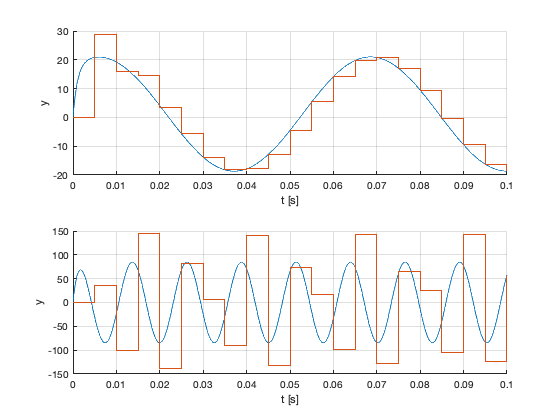

%   continuous-time controller - forced sinusoidal response
tc=0:0.0001:0.1;
uc = sin(wbar*tc); 
y_Cs_wbar= lsim(Cs,uc,tc);
uc = sin(wtest1*tc); 
y_Cs_wtest1= lsim(Cs,uc,tc);

%   discrete-time controller - forced sinusoidal response
td=0:Ts:0.1;
ud = sin(wbar*td); 
y_Cd_wbar= lsim(Cd_p10,ud,td);
ud = sin(wtest1*td); 
y_Cd_wtest1= lsim(Cd_p10,ud,td);

%   plot forced responses 
figure
subplot(2,1,1)
grid on
hold on
plot(tc,y_Cs_wbar)
stairs(td,y_Cd_wbar)
ylabel('y'); xlabel('t [s]');

subplot(2,1,2)
grid on
hold on
plot(tc,y_Cs_wtest1)
stairs(td,y_Cd_wtest1)
ylabel('y'); xlabel('t [s]');